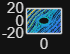

U = 1;
alpha = 1;
a = 6;
b = 6*0.8;
L = 20;
P = 200;

x = linspace(-L,L,P);
y = linspace(-L,L,P);

[x,y] = meshgrid(x,y);

z = x + 1i*y;

Z = z + b^2./(z - 1);

Z_Cam = z + b^2./(z - 1 + 1i);

f = U*z*exp(-1i*alpha);
milne = U*a^2*exp(1i*alpha)./z;

w = f + milne;

dwdz = U*exp(-1i*alpha)-U*a^2*exp(1i*alpha)./z.^2;
u = real(dwdz);
v = -imag(dwdz);

psi = imag(w);
psi_f = psi;

mask = abs(z) < a - 2*L/P;
psi(mask) = NaN;
u(mask) = NaN;
v(mask) = NaN;

contour(x,y,psi,10)
hold on
contour(x,y,psi,[0,0])
streamslice(x, y, u, v, 0.5);

xlim([-L,L])
ylim([-L,L])

hold off

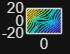


contour(real(Z),imag(Z),psi,20)
hold on
contour(real(Z),imag(Z),psi,[0,0])

xlim([-L,L])
ylim([-L,L])

hold off

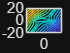


contour(real(Z_Cam),imag(Z_Cam),psi,20)
hold on
contour(real(Z_Cam),imag(Z_Cam),psi,[0,0])

xlim([-L,L])
ylim([-L,L])

hold off